## get_RSV_data.mlx

load VacRatePerDay101Ages_2018_19.mat %VacRatePerDay101 from get_RSV_data.mlx  335 day x 101 ages
VacRatePerDay101_US = VacRatePerDay101;

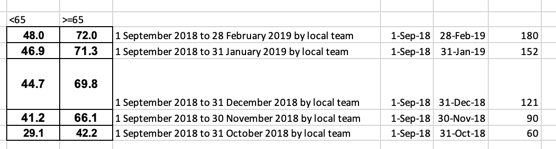

data_UK = [48,72,360;48,72,180;46.9000000000000,71.3000000000000,152;44.7000000000000,69.8000000000000,121;41.2000000000000,66.1000000000000,90;29.1000000000000,42.2000000000000,60;0,0,0];
VacRatePerDay101_UK = [];

for i = 7:-1:2
    tempX = (data_UK(i, 3)+1): (data_UK(i-1, 3)) ;
    tempOlder = -data_UK(i, 2)+ (data_UK(i-1, 2)) ;
    tempAdult = -data_UK(i, 1)+ (data_UK(i-1, 1)) ;
    VacRatePerDay101_UK = [VacRatePerDay101_UK; tempAdult./length(tempX).*ones(length(tempX), 65), ...
        tempOlder./length(tempX).*ones(length(tempX), 101-65)];
end
VacRatePerDay101_UK = VacRatePerDay101_UK./100;

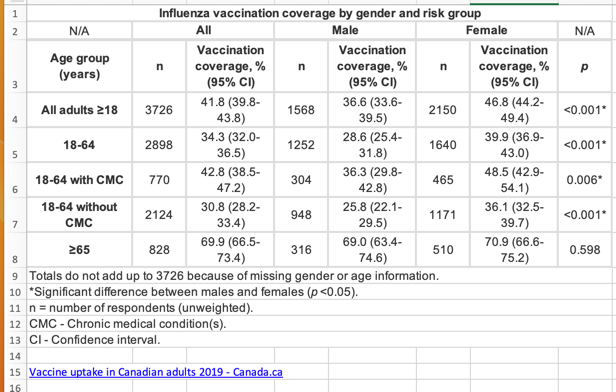

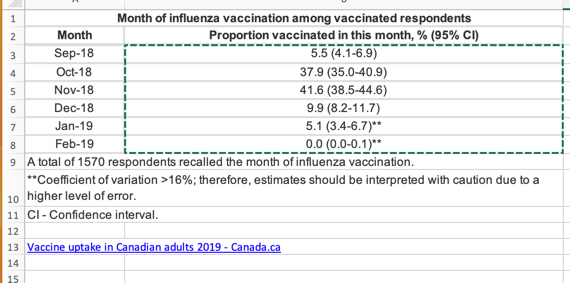

VacRatePerDay101_Canada = [];
data_Canada = [5.5, 37.9, 41.6, 9.9, 5.1, 0];
num_days = [];
cal = calendar(2018, 9); num_days = [num_days; sum(cal(:) ~= 0)];
cal = calendar(2018, 10);num_days = [num_days; sum(cal(:) ~= 0)];
cal = calendar(2018, 11);num_days = [num_days; sum(cal(:) ~= 0)];
cal = calendar(2018, 12);num_days = [num_days; sum(cal(:) ~= 0)];
cal = calendar(2019, 1); num_days = [num_days; sum(cal(:) ~= 0)];
cal = calendar(2019, 2); num_days = [num_days; sum(cal(:) ~= 0)];

for i=1:length(data_Canada)
    VacRatePerDay101_Canada = [VacRatePerDay101_Canada; ...
        data_Canada(i)./num_days(i).*ones(num_days(i), 65), ...
        data_Canada(i)./num_days(i).*ones(num_days(i), 101-65)];
end
VacRatePerDay101_Canada = [VacRatePerDay101_Canada; zeros(200,101)];
VacRatePerDay101_Canada = VacRatePerDay101_Canada./100;

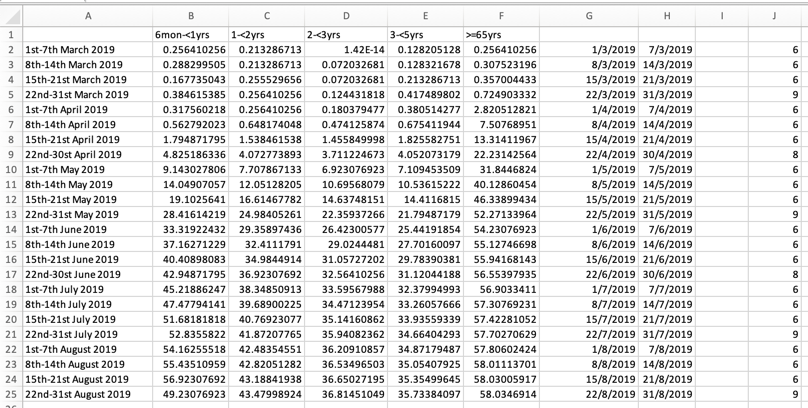

Data_Australia = [0.256410256000000,0.213286713000000,1.42000000000000e-14,0.128205128000000,0.256410256000000,0.000165098233448902,0.00115568763414231,6;0.288299505000000,0.213286713000000,0.0720326810000000,0.128321678000000,0.307523196000000,0.00132078586759122,0.00231137526828463,6;0.167735043000000,0.255529656000000,0.0720326810000000,0.213286713000000,0.357004433000000,0.00247647350173353,0.00346706290242694,6;0.384615385000000,0.256410256000000,0.124431818000000,0.417489802000000,0.724903332000000,0.00363216113587585,0.00511804523691597,9;0.317560218000000,0.256410256000000,0.180379477000000,0.380514277000000,2.82051282100000,0.000123823675086677,0.000866765725606736,6;0.562792023000000,0.648174048000000,0.474125874000000,0.675411944000000,7.50768951000000,0.000990589400693413,0.00173353145121347,6;1.79487179500000,1.53846153800000,1.45584999800000,1.82558275100000,13.3141196700000,0.00185735512630015,0.00260029717682021,6;4.82518633600000,4.07277389300000,3.71122467300000,4.05207317900000,22.2314256400000,0.00272412085190688,0.00371471025260030,8;9.14302780600000,7.70786713300000,6.92307692300000,7.10945350900000,31.8446824000000,9.90589400693413e-05,0.000693412580485389,6;14.0490705700000,12.0512820500000,10.6956807900000,10.5361522200000,40.1286045400000,0.000792471520554730,0.00138682516097078,6;19.1025641000000,16.6146778200000,14.6374815100000,14.4116815000000,46.3389943400000,0.00148588410104012,0.00208023774145617,6;28.4161421900000,24.9840526100000,22.3593726600000,21.7948717900000,52.2713396400000,0.00217929668152551,0.00307082714214958,9;33.3192243200000,29.3589743600000,26.4230057700000,25.4419185400000,54.2307692300000,8.25491167244510e-05,0.000577843817071157,6;37.1627122900000,32.4111791000000,29.0244481000000,27.7016009700000,55.1274669800000,0.000660392933795608,0.00115568763414231,6;40.4089808300000,34.9844914000000,31.0572720200000,29.7839038100000,55.9416814300000,0.00123823675086677,0.00173353145121347,6;42.9487179500000,36.9230769200000,32.5641025600000,31.1204418800000,56.5539793500000,0.00181608056793792,0.00247647350173353,8;45.2188624700000,38.3485091300000,33.5956798800000,32.3799499300000,56.9033411000000,7.07563857638152e-05,0.000495294700346706,6;47.4779414100000,39.6890022500000,34.4712395400000,33.2605766600000,57.3076923100000,0.000566051086110521,0.000990589400693413,6;51.6818181800000,40.7692307700000,35.1416086200000,33.9355933900000,57.4228105200000,0.00106134578645723,0.00148588410104012,6;52.8355822000000,41.8720776500000,35.9408236200000,34.6640429300000,57.7027062900000,0.00155664048680393,0.00219344795867827,9;54.1625551800000,42.4835455100000,36.2091085700000,34.8717948700000,57.8060242400000,6.19118375433383e-05,0.000433382862803368,6;55.4351095900000,42.8205128200000,36.5349650300000,35.0540792500000,58.0111370100000,0.000495294700346706,0.000866765725606736,6;56.9230769200000,43.1884193800000,36.6502719500000,35.3549964500000,58.0300591700000,0.000928677563150074,0.00130014858841010,6;49.2307692300000,43.4799892400000,36.8145104900000,35.7338409700000,58.0346914000000,0.00136206042595344,0.00191926696384349,9];
VacRatePerDay101_Australia = [];

for i=1:size(Data_Australia, 1)
    VacRatePerDay101_Australia = [VacRatePerDay101_Australia; ...
        Data_Australia(i, 1:3)./Data_Australia(i,end).*ones(Data_Australia(i,end),1), ...
        Data_Australia(i, 4)./Data_Australia(i,end).*ones(Data_Australia(i,end),1), ...
        zeros(1,64-5+1).*ones(Data_Australia(i,end),1), ... %5-64
        Data_Australia(i, 5)./Data_Australia(i,end).*ones(Data_Australia(i,end),101-64)];
end
VacRatePerDay101_Australia = [VacRatePerDay101_Australia; zeros(200,101)];
VacRatePerDay101_Australia = VacRatePerDay101_Australia./100;


opts = spreadsheetImportOptions("NumVariables", 103);

% Specify sheet and range
opts.Sheet = "data";
opts.DataRange = "A2:CY1437";

% Specify column names and types
opts.VariableNames = ["Country_Name", "Date", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68", "VarName69", "VarName70", "VarName71", "VarName72", "VarName73", "VarName74", "VarName75", "VarName76", "VarName77", "VarName78", "VarName79", "VarName80", "VarName81", "VarName82", "VarName83", "VarName84", "VarName85", "VarName86", "VarName87", "VarName88", "VarName89", "VarName90", "VarName91", "VarName92", "VarName93", "VarName94", "VarName95", "VarName96", "VarName97", "VarName98", "VarName99", "VarName100", "VarName101", "VarName102", "VarName103"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
VacRatesCountries = readtable("VacRatesCountries.xlsx", opts, "UseExcel", false);
VacRates.Country_Names = VacRatesCountries.Country_Name;
VacRates.Values = table2array(VacRatesCountries(:,3:end));
% clear opts